# Chemical Reaction

## Task 1

Define the time interval for the first 3 minutes of the reaction (t=0 to t=3) and assign it to the variable `tRange`.

tRange=[0 3]

tRange =      0     3


## Task 2

There are initially 100 molecules of x and no molecules of y.

 Create a column vector to represent the initial conditions, and assign it to the variable `Y0`.

 Remember that each chemical must appear in the same order in the  initial condition vector and the ODE function vector. You can find the  ODE function `reactionODE` at the bottom of the script.

Y0=[100;0]

Y0 =    100
     0


## Task 3 

The syntax to solve a system of ODEs using `ode45` is the same as the syntax for a single ODE:

`[``tSol``,``YSol``]` `=` `ode45``(``@``odefun``,``tRange``,``Y0``)`

Task

Use `ode45` to solve the system of ODEs, and assign the outputs to `tSol` and `YSol`. 

The system of ODEs has been implemented in the local function `reactionODE`.

[tSol, YSol]=ode45(@reactionODE,tRange,Y0)

tSol =          0
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000
    0.0000


YSol =   100.0000         0
   99.9999    0.0001
   99.9999    0.0001
   99.9998    0.0002
   99.9998    0.0002
   99.9995    0.0005
   99.9993    0.0007
   99.9990    0.0010
   99.9988    0.0012
   99.9975    0.0025


## Task 4

Extract the column vector that represents the number of molecules of x from the solution matrix `YSol`. Assign it to the variable `x`.

x=YSol(:,1)

x =   100.0000
   99.9999
   99.9999
   99.9998
   99.9998
   99.9995
   99.9993
   99.9990
   99.9988
   99.9975


## Task 5

Extract the column vector that represents the number of molecules of y from the solution matrix `YSol`. Assign it to the variable `y`.

y=YSol(:,2)

y =          0
    0.0001
    0.0001
    0.0002
    0.0002
    0.0005
    0.0007
    0.0010
    0.0012
    0.0025


**Visualize *****x***** and *****y***

Do not edit. This code visualizes the solution.

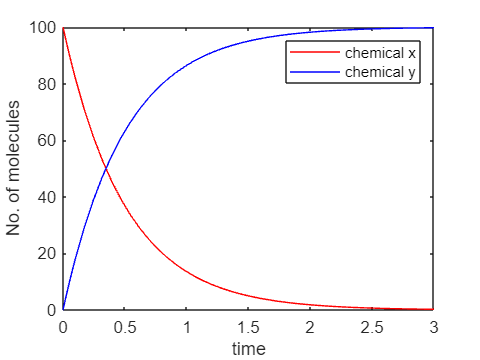

plot(tSol,x,"r")
hold on
plot(tSol,y,"b")
hold off

% Annotate plot
legend("chemical x","chemical y")
xlabel("time")
ylabel("No. of molecules")

**ODE function**

Do not edit. This code defines the ODE function for the system of ODEs

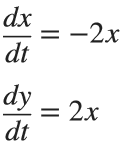

function dYdt = reactionODE(t,Y)
x = Y(1); % chemical x
y = Y(2); % chemical y
dxdt = -2*x;
dydt = 2*x;
dYdt = [dxdt;dydt];
end